# Optimizing neural networks

While neural networks are really popular for artificial intelligence research and applications, [they can be difficult to train them](https://machinelearningmastery.com/why-training-a-neural-network-is-hard/) without overfitting. We'll discuss common issues encountered when training neural network and potential strategies to address these issues.

## Initializing parameters

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

### Setting w and b to be all zeros

We'll go back to our toy dataset with 20 observations and 3 features to illustrate the results when w and b are all zero.

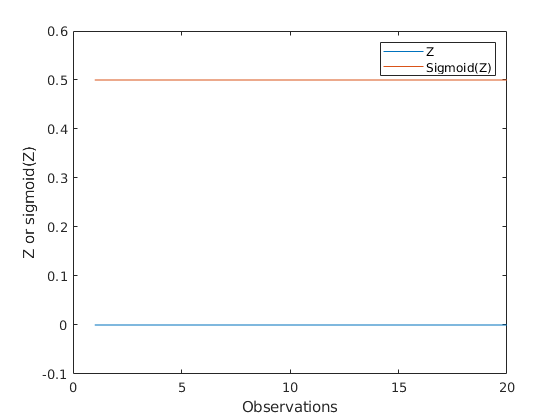

rng(2);

% Toy dataset with 3 features and 20 observations
Xtrain = normrnd(0, 1, [20, 3]);
w = [0, 0, 0]; b = zeros([20, 1]); % Set weights and biases to all equal 0
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'}); ylim([-0.1 0.6]);
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features because there's is no gradient to compute ($\textrm{dW}\;\textrm{and}\;\textrm{db}=0$) during back propagation.

### Setting w and b to be all ones

Now let's think about what happens when `w` and `b` are set to all ones and we apply the sigmoid activation function. 

The features end up being scaled to logit values in the range [0, 1] by the activation function.  While this is not necessarily a bad thing, this does slow down our computations, especially with $L$ layer networks. 

### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning (ie setting all weights and biases equal to 0) and we allow the neural network to easily approach a better solution through back propagation / gradient descent. The built-in MATLAB functions automatically performs symmetry breaking when training neural networks.

## Overfitting Neural Networks

Recall that the underlying objective in machine learning is to build a model that balances the model's ability to balance bias and variance. This is known as the **bias-variance tradeoff**. Neural networks are highly nonlinear models with high variance and low bias, and are thus susceptible to overfitting. The modules below will discuss strategies to address model overfitting.

### Regularization

One way to address this issue is to use **regularization** to further penalize the loss and gradients. This reduces our chance of overfitting by reducing the number of possible solutions our model can predict. We'll discuss two methods for regularization: **LASSO** or **L1 regularization** (not built into the MATLAB neural networks function), and **Ridge** or **L2 regularization **(built into the `trainOptions` function in MATLAB). 

#### Intuition of L1 (LASSO) and L2 (Ridge) regularization

To visualize the potential solution space of our model, we have drawn an ellipsoid shaded in blue, The weight in the center $\left(w_{\textrm{NN}} \right)$ is the weight that minimizes the cost $J$. However, $w_{\textrm{NN}}$ may not be optimal: as an example, the model may have overfit the data, resulting in a minimized training cost, but a non-generalizable $w_{\textrm{NN}}$. 

One strategy is to shrink the number of potential solutions by forcing the model to minimize the coefficient value. This is what regularization does, and it discourages a model from being too flexible to avoid overfitting. The natural question we should be asking is, how do we choose weights that minimzes $J$ while minimizing $w$.

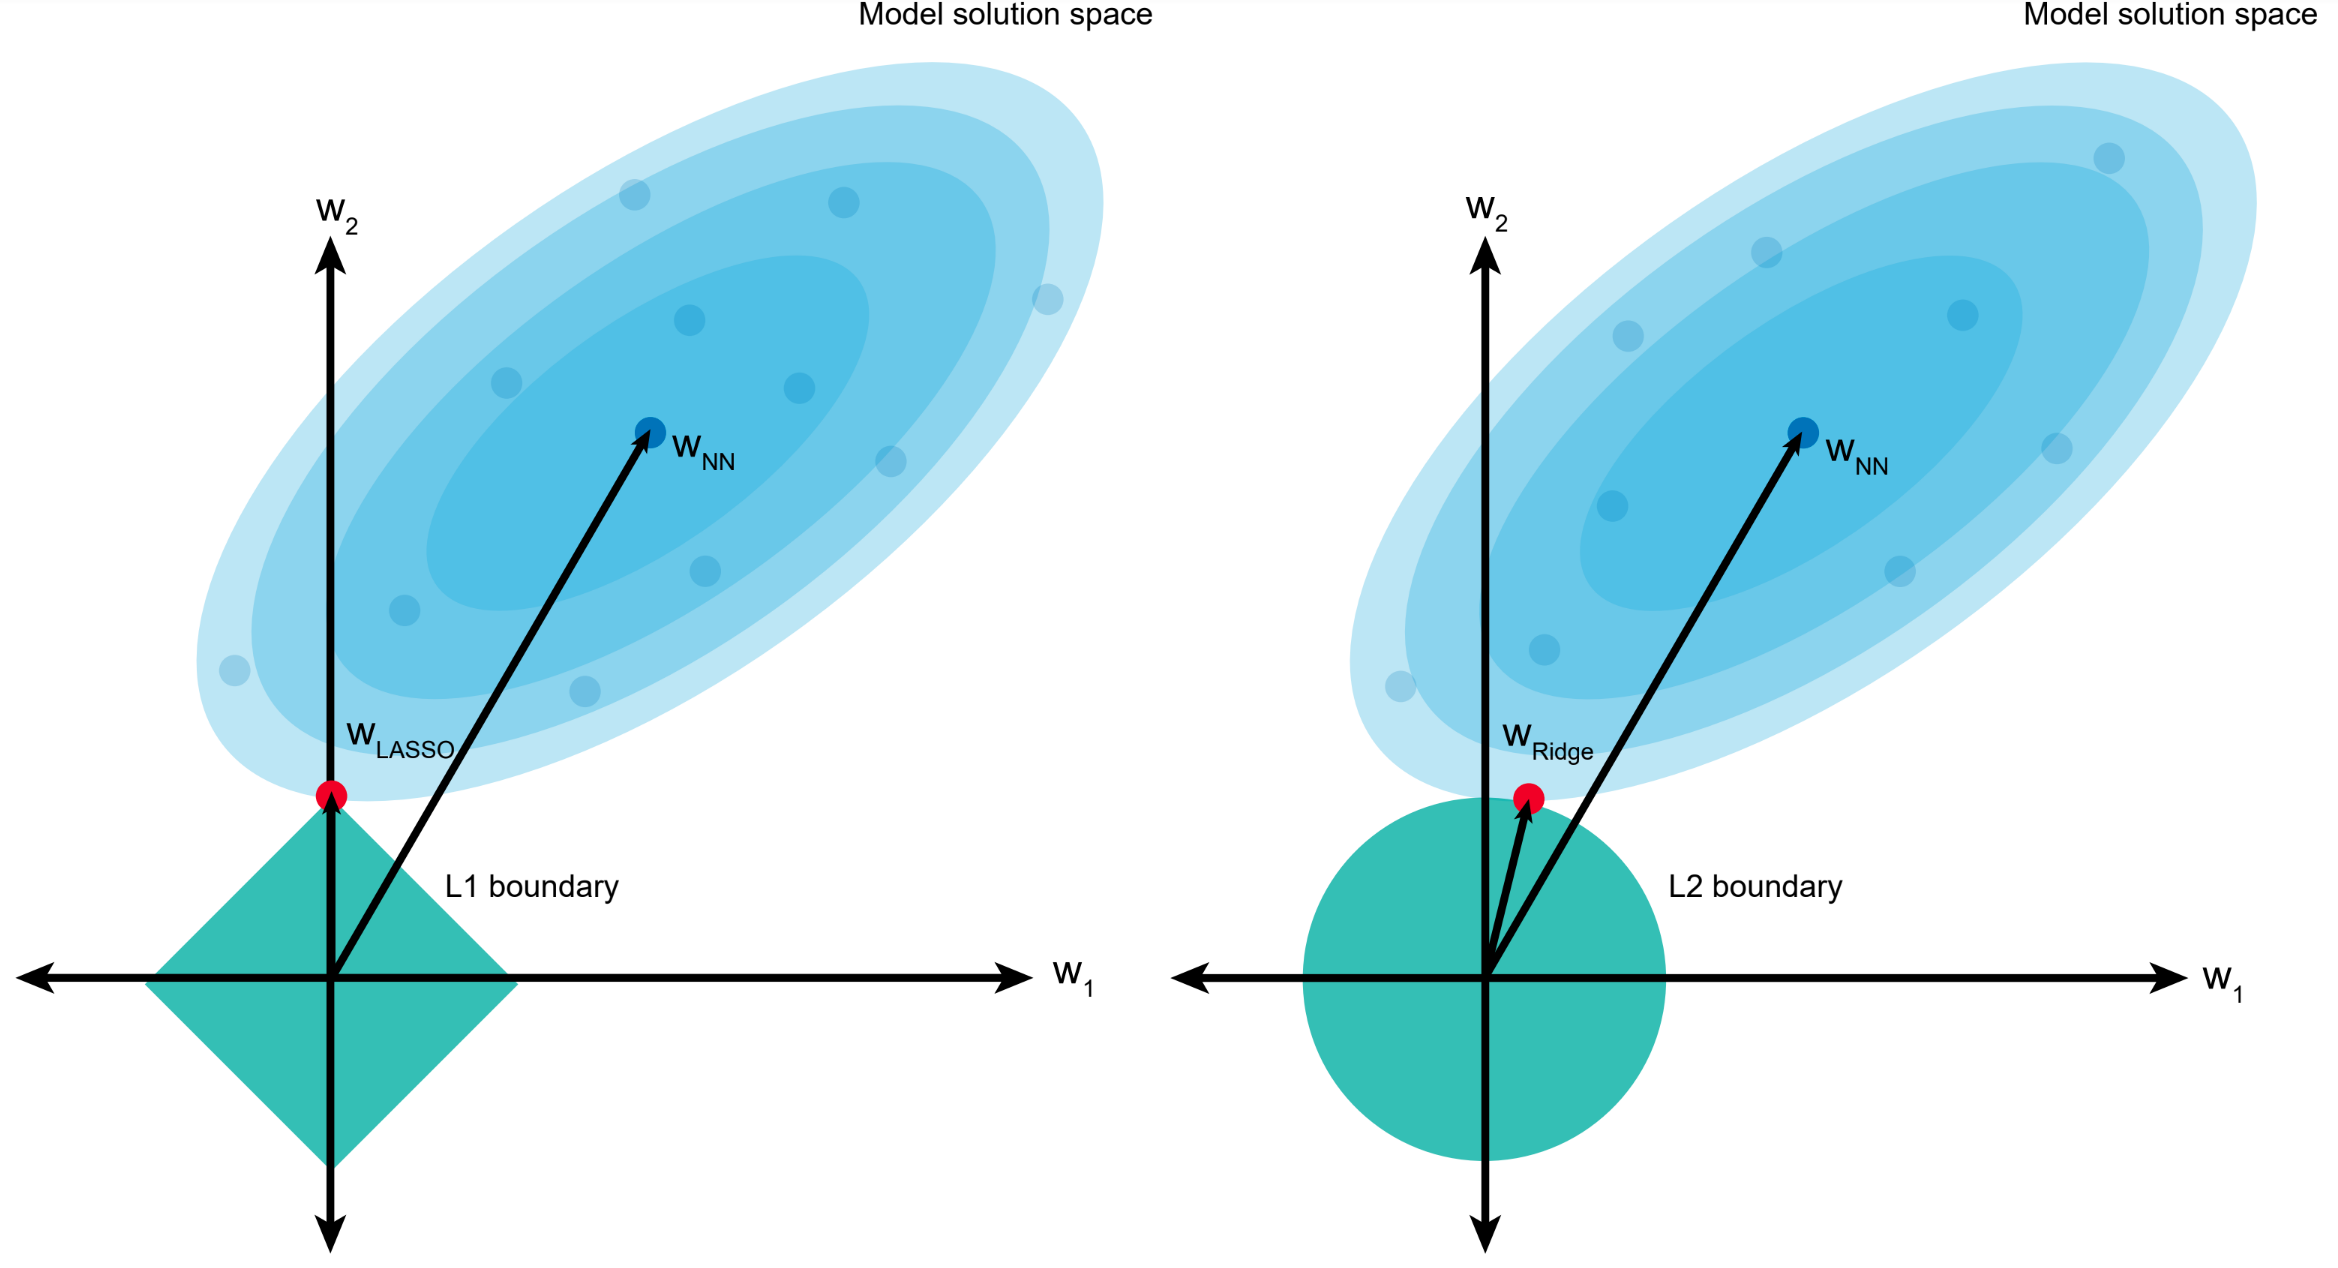

We can formularize this problem as $J\left(w\right)=L\left(y_{\textrm{train}} ,y_{\textrm{pred}} \right)-\lambda$$\Omega \left(w\right)$, where $\Omega \left(w\right)$ is a penalty function for the model coefficient, and $\lambda$ is a tuning parameter that tells the model how stringent we want our penalty to be to select the best coefficient. If we penalize our model from the coefficients with the largest magnitude, we get the **LASSO** or **L1** regularization term: $\lambda \sum_{i=1}^p \left|w_i \right|$. The shape of the LASSO constraint looks like the plot to the left. Note that because we have a diamond shaped boundary, LASSO can set coefficients (ie $w_2$) directly to 0, resulting in the final weight set $\left(w_{\textrm{LASSO}} \right)$ shown in red. Thus, it performs feature selection for us - it will tell the model if some predictors are useless for minimizing the model error.

If we want to add this constraint to the cross-entropy loss function as the base objective function, we can do it using the formation below:


$${J\left(w\right)}_{\textrm{LASSO}} =-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack +\lambda \sum_i {\left|w\right.}_i \left|\right.$$


However, what if we think that the predictors in our dataset do have small, but important effects on the model prediction? One way to accept coefficients that are small but non-zero and still minimize $J$ is to square the regularization term so that the boundary becomes a circle. This is called the **Ridge** or **L2** regularization term: $\lambda \sum_{i=1}^p w_i^2$. Note that the Ridge solution $w_{\textrm{Ridge}}$ (red) is a small non-zero value that minimizes $J$. The formulation for the cross-entropy loss function with the Ridge constraint is shown below:


$${J\left(w\right)}_{\textrm{Ridge}} =-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack +\lambda \sum_i {w_i }^2$$


Below, we'll discuss how to implement regularization with our neural networks.

#### Implementing L1 (LASSO) regularization with our custom Shallow Neural Network

Unfortunately, LASSO is not a built-in option with the Deep Learning toolbox and other MATLAB neural network functions. The following code adds on LASSO regularization on the cross entropy loss function and subsequent back propagation for our custom shallow neural network.

#### MATLAB Neural Network L2 Regularization using the Deep Neural Network Toolbox

MATLAB's Deep Learning Toolbox currently only supports L2 (Ridge) regularization as a built-in function using the `trainingOptions` object. To specify the tuning parameter $\lambda$ to be 1E-5, we can use the following syntax:

Note that in both regularization cases, the tuning parameter $\lambda$ would be another hyperparameter we have to tune with k-fold cross validation if we decide to regularize our neural network to determine the best boundary size to use.

#### Dropout layers

Overfitting is a result of a model fitting to noise in the dataset, rather than the real signal. Instead of constraining the model, [Srivastava et al., 2014](https://www.cs.toronto.edu/~hinton/absps/JMLRdropout.pdf) suggested to do something pretty clever: randomly and temporarily remove activation nodes in the hidden layer (essentially, set it to 0 for a given epoch), along with the incoming and outgoing weights. 

This is another form of regularization, in that the model is pruned during every epoch. It works because during the pruning process, we eliminate relationships between nodes that may be co-dependent, and causing errors in the model by random chance. By making the model more sparse, it learns the more important weights better, and increases its robustness.

To add dropout layers in the model built from the `trainNetwork` function, we can specify this as a `dropoutLayer` object when building our `layers` array:

### Early stopping

Early stopping is another strategy to avoid overfitting, where we will stop training the model once the performance of the model goes down (when the model holdout error increases during an epoch). Luckily, MATLAB automatically does early stopping with the Deep Learning Toolbox.

## Data scaling

While neural networks can capture trends in complex / non-standardized datasets, there are several advantages to train using standardized data:

- We reduce the training time because we're examining a smaller range of values and thus reducing the time it takes for the weights to converge to an optimal value.

- We reduce the change of getting stuck in a local optima when computing the loss due to chance by minimizing the dynamic range of the data.

There are two common methods to scale our data depending on how we wish to interpret each feature: the **Z-score method**, and the **min-max scaling method**. 

### Z-score scaling


$$X_{\textrm{zscore}} =\frac{X_{\textrm{ij}} -\textrm{mean}\left(X_j \right)}{\textrm{std}\left(X_j \right)}$$


The **z-score method** will ensure that each value is scaled to have a mean of 0 and standard deviation of 1. The `zscore` function in MATLAB automatically does this, however, you can also perform this computation manually. Shown below are two ways of computing the z-scores for $X_{\textrm{train}}$.

### Min-max scaling


$$X_{\textrm{minmax}} =\frac{X_{\textrm{ij}} -\min \left(X_j \right)}{\max \left(X_j \right)-\min \left(X_j \right)}$$


While useful, z-score scaling can produce results that don't necessarily reflect true values, especially if our feature is composed of only positive values. In those cases, **min-max scaling** can actually be better, where we scale all data points between a value of [0, 1].  Shown below are two ways of rescaling $X_{\textrm{train}}$.

## Optimizing neural network performance

Recall that we've been using a naive approach to determining the number of activation nodes in our neural network, where we assumed two activation nodes are best because we're trying to split the data into two classes. While it's a good starting point, it's another assumption we're imposing on the model.

To determine the best number of activation nodes to use for either a single layer or `L` layers, we need to optimize this hyperparameter in a systematic way. One way to do so is to run k-fold cross validation, and see which number of activation nodes best improves the accuracy / minimzes the error from the model. 

### Hyperparameter tuning

Hyperparameter tuning is finding the best set of hyperparameters that will optimize the k-fold cross validation accuracy of our model without overfitting. So far, we have discussed the following set of hyperparameters:

- Number of activation nodes for each layer (Number of potential parameters: L layers * n nodes)

- The learning rate (Number of potential parameters: 100, assuming we sample [0.01, 1] in 0.01 increments. Estimate is higher if we want to explore lower / higher values)

- The number of epochs / iterations (Number of potential parameters: 500)

- The activation function (Number of potential parameters: 3)

There are about $15,000,000$ different possible combinations from 4 parameters to sample, not including the training/test size and optimizing the number of k-folds in cross validation. Yikes. 

A **complete grid search** explores every single combination, which is not feasible on our laptops. Another method that balances the amount of time searching for an optimal model and model performance is a **random grid search**.

#### Random Grid Search

A **random grid search** takes in a random combination of hyperparameters to find the best set of hyperparameters to use. There are several benefits to randomized grid search, namely that the search time is decreased by a lot. 

Instead of searching every single combination of parameters, we can chose the number of times we want to run our random search (ie 30 different combinations, as MATLAB does by default) to get the best hyperparameters. Additionally, [Bergestra and Bengio, 2012](http://www.jmlr.org/papers/volume13/bergstra12a/bergstra12a.pdf) found that random search can perform just as well, if not better, than a grid search. 

To run a random grid search, we can use the following code blocks to sample different number of activation nodes in the hidden layer of a shallow neural network and the activation functions for our custom shallow neural network.

### Hyperparameter tuning using MATLAB's Builtin functions

We can perform a random grid search using MATLAB's neural network functions, and store the accuracy values to choose the best parameters. The example below will optimize the number of nodes and the activation function to use in a shallow neural network.

First create a distribution of values to sample for the number of nodes and the activation functions to use. The `softmaxLayer` activation function is equivalent to the cross-entropy cost function for binary classification.

For 30 iterations, we'll construct a new neural network using the `trainNetwork` function while sampling different hyperparameters during each iteration. We'll store the hyperparameters sampled in the `layerSampled` cell array.

We'll keep these training options the same. However, we can technically also sample different training options if we really wanted to.            

Next, we'll train the model using the `trainNetwork` function built into MATLAB, use the model to make a prediction, construct a confusion matrix, and get an accuracy using the confusion matrix. We'll store the accuracies in the `accuracy` cell array and the

To choose the best model, we can get the index of the model that had the best accuracy and get either the models or hyperparameters that got us the best accuracy. Then we can do whatever we want with the best model or set of hyperparameters.

## Hardware considerations for optimizing neural network performance 

The datasets and models we have been working with so far have been fairly manageable on a laptop. We'll now discuss some methods that you can use to speed up the computations from training models with large datasets and more complex model architectures. 

### Parallel computing

When working with really large datasets, computational efficiency becomes more important. One way to deal with more complex models or computing large datasets for any model is to run MATLAB with the [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html#scale-up-matlab-applications), which splits the computation process between different processing units if you have a multi-core machine.

To implement parallel processing with a shallow neural network, we can use the following snippet of code to use the parallel computing toolbox. 

### Training using a GPU

The Parallel Computing Toolbox also allows us to run our code on a GPU if your local machine or computing cluster if available. Currently MATLAB only supports NVIDIA GPUs. To train a deep neural network using a GPU, MATLAB automatically detects and uses the `gpu` from the `ExecutationEnvironment` argument. However, if we want to use both the `gpu` and `cpu`, we can specify this argument to `parallel`.

Alternatively, we can specify which datasets we want to be fed into a GPU computation using the `gpuArray` function. If you do have a GPU, these arrays will automatically be detected for GPU use. 

Finally, if we want to use the `trainNetwork` function to train a deep neural network using a GPU, we can specify the GPU as a hyperparameter in the function. 

## Summary

We have covered strategies to prevent model overfitting, systematic ways to tune hyperparameters, and ways to utilize our hardware for more efficient neural network training. 

### Built in MATLAB functions covered in this lesson

`fitnet / feedforwardnet:`    Constructs a neural network structure.

`train:                    `Trains the neural network.

`plotperf:                 `Plots the cost curves from the trained neural network.

`crossentropy:             `Computes the cross-entropy cost.

`view:                     `Visualize the neural network structure using the MATLAB GUI. 

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat`

### List of custom functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$dataset.

`activationFnc:            `Transforms the dataset using a non-linear function.

`costFunction:`                            Computes the cost value from the model.

`crossValidate:`                          Performs k-fold cross validation.

`SNN:`                                               Trains a shallow neural network.

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence